# **Procesamiento Digital de Señales de Radar FMCW para la**

## **Estimación de Distancia y Velocidad de Objetos mediante MATLAB**

Curso

**Procesamiento de Señales e Imágenes Digitales (IEE239-08M2)**

Docente

**Ing. Juan Miguel Urco**

Integrantes

- **20185876** – **Quintanilla Quispe, Brandon Felix**

- **20210670** – **Asencios Gomez, Leonardo William**

- **20210792** – **Vásquez Bernal, Carlos Alberto**

Ciclo académico

**2026-2**

Pontificia Universidad Católica del Perú

**Facultad de Ciencias e Ingeniería**

## 1. Carga e inspección inicial de los datos

**Objetivo**

Antes de realizar cualquier procesamiento es necesario conocer cómo está almacenada la información entregada por el radar. Cada archivo `adc_Data.mat` corresponde a una adquisición del experimento y contiene las muestras digitalizadas de los cuatro canales receptores del radar. En esta primera etapa únicamente se cargan e inspeccionan los datos; todavía no se aplica ningún procesamiento de frecuencia. La finalidad es verificar el nombre de la variable almacenada en el archivo, las dimensiones de la tabla y los nombres de las columnas correspondientes a cada receptor.

clearvars;
clc;
close all;
load(fullfile("Fast_part1", "1", "adc_Data.mat"));

whos

  Name                      Size                 Bytes  Class    Attributes

  adc_DataTable      26214400x4             1677723287  table              



adc_DataTable(1:5,:)

ans = 5×4 table
    adc_DataRX1    adc_DataRX2    adc_DataRX3    adc_DataRX4
    ___________    ___________    ___________    ___________

     317-23i        152-99i        449+18i        330-131i  
     347-69i        134-206i       463-116i       322-269i  
     322-165i        38-210i       390-177i       211-352i  
     241-194i        38-205i       397-226i       186-379i  
     224-209i         6-243i       370-341i       103-493i  


***En esta etapa todavía no sabemos qué frecuencias, distancias o movimientos existen. Únicamente hemos comprobado que MATLAB puede acceder correctamente a la adquisición y conocemos cómo están organizados los datos.***

## 2. Observación inicial de las componentes I y Q

**Objetivo**

Los datos entregados por cada receptor son complejos y pueden representarse como:


$$x\left\lbrack n\right\rbrack =I\left\lbrack n\right\rbrack +\textrm{jQ}\left\lbrack 
n\right\rbrack$$


donde:


$$I\left\lbrack n\right\rbrack =\textrm{Re}\left\lbrace x\left\lbrack n\right\rbrack 
\right\rbrace$$


y:


$$Q\left\lbrack n\right\rbrack =\textrm{Im}\left\lbrace x\left\lbrack n\right\rbrack 
\right\rbrace$$


En esta etapa observaremos visualmente ambas componentes para comprender cómo se presenta la señal digitalizada por el radar. Para simplificar el análisis inicialmente utilizaremos únicamente el receptor RX1. Las funciones `real()` e `imag()` utilizadas aquí corresponden directamente a las herramientas de números complejos. Usaremos sólo las primeras 1000 muestras, con ello tendríamos las componentes reales y complejas de la señal IF después del ADC. Ù*nicamente para realizar una inspección visual general*.

RX1 = adc_DataTable.adc_DataRX1;
x = RX1(1:1000);
I = real(x);
Q = imag(x);

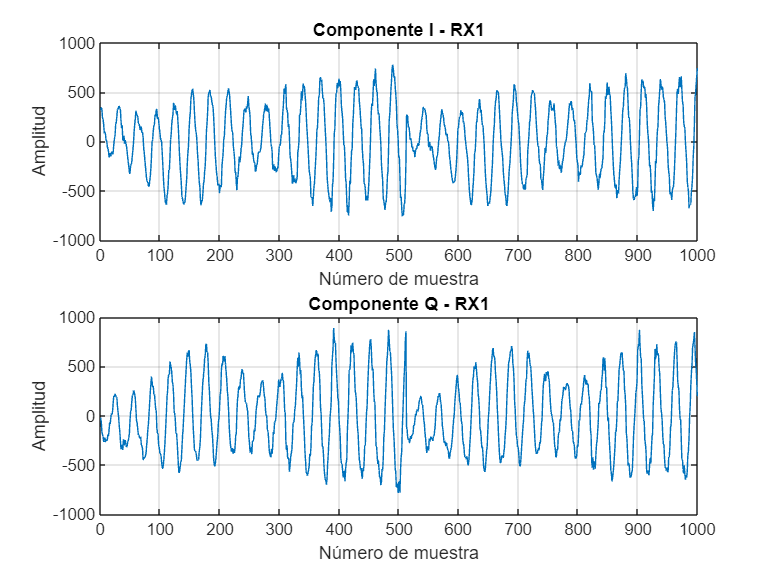

figure;
subplot(2,1,1);
plot(I);
grid on;
xlabel('Número de muestra');
ylabel('Amplitud');
title('Componente I - RX1');

subplot(2,1,2);
plot(Q);
grid on;
xlabel('Número de muestra');
ylabel('Amplitud');
title('Componente Q - RX1');

Ambas presentan un comportamiento claramente oscilatorio, además la amplitud de las oscilaciones no permanece constante, hay zonas donde las oscilaciones son mayores y otras donde disminuyen, esto indica que la señal recibida no corresponde a una única sinusoide ideal de amplitud constante, sino a una combinación de diferentes sinusoides.

Por ejemplo aproximadamente entre las muestras 300 y 500 se observan amplitudes mayores, mientras que alrededor de las muestras 500–600 la amplitud es mas pequeña. Aca lo que estamos viendo es el comprotamiento de 1 chirp completo [512 muestras] y 488 muestras del segundo chirp. 

## 3. Análisis temporal de un chirp completo

**Objetivo**

Las 1000 muestras anteriores fueron utilizadas solamente para visualizar la señal. Para iniciar el análisis físico del radar necesitamos trabajar con una estructura conocida del experimento.

Cada chirp contiene 512 muestras y la frecuencia de muestreo del ADC es de 10 MHz.

Por ello analizaremos exactamente las primeras 512 muestras, que corresponden al primer chirp del primer frame de RX1.


$$\textrm{Fs}=10\;000\;000\;\frac{\textrm{Muestras}}{S}$$



$$\textrm{Ts}=\frac{1}{\textrm{Fs}}=0\ldotp 1\;\textrm{us}$$


Por tanto, 512 muestras representan: $512*0\ldotp 1\;\textrm{us}=51\ldotp  2\;\textrm{us}$

**De esta manera podremos observar el primer chirp utilizando un eje de tiempo físico en microsegundos.**

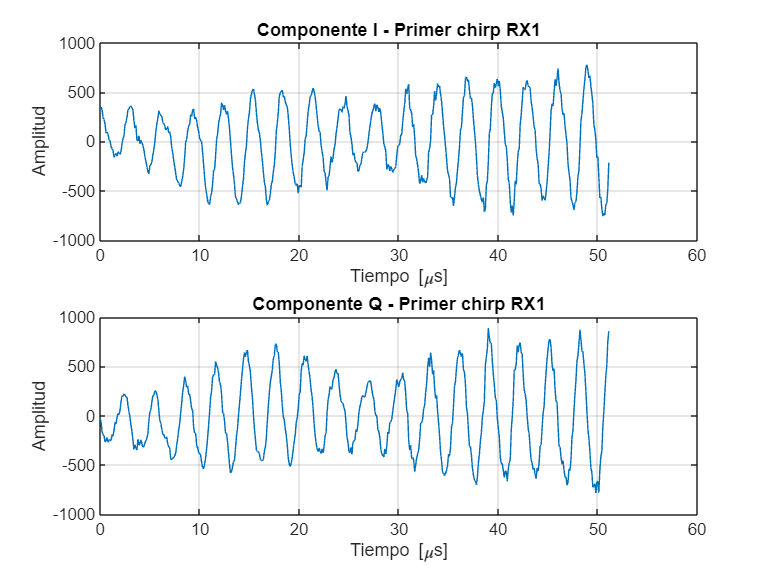

Fs = 10000000;
N = 512;
x = RX1(1:N);
I = real(x);
Q = imag(x);
t = (0:N-1)/Fs;
figure;

subplot(2,1,1);
plot(t*1000000,I);
grid on;
xlabel('Tiempo [\mus]');
ylabel('Amplitud');
title('Componente I - Primer chirp RX1');

subplot(2,1,2);
plot(t*1000000,Q);
grid on;
xlabel('Tiempo [\mus]');
ylabel('Amplitud');
title('Componente Q - Primer chirp RX1');

Estamos observando físicamente cómo varían I y Q durante un chirp, visualmente se observan aproximadamente 17 oscilaciones durante unos 51.2 us, estimando la frecuencia de este primer chirp.


$$f=\frac{17}{51\ldotp 2*{10}^{-6} }=332\;K\textrm{Hz}$$


Esto haciendo una estimacion visual.

## 4. Análisis en frecuencia del primer chirp

**Objetivo**

Hasta ahora hemos observado la señal en el dominio del tiempo. Ahora queremos responder:

**¿Qué componentes de frecuencia contiene el primer chirp recibido?**

Para ello aplicaremos la DFT mediante la función `fft().`

`Recordemos que cada bin esta separado por` $\Delta f=\frac{\textrm{Fs}}{N}=\frac{10000000}{512}=19\;531\ldotp  25\;\textrm{Hz}$ Así, cada bin consecutivo de la FFT representa un cambio aproximado de 19.53 KHz.

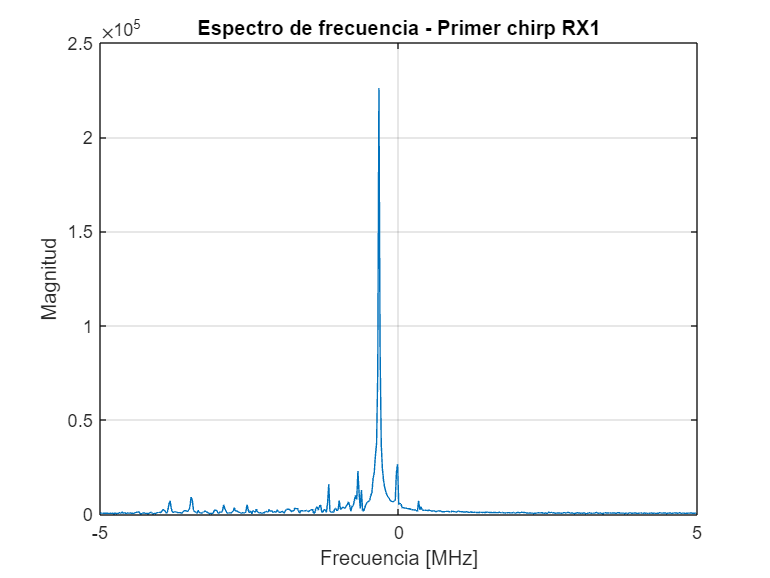

X = fft(x);

Xc = fftshift(X);

f = (-N/2:N/2-1)*(Fs/N);

figure;
plot(f/1000000,abs(Xc));
grid on;
xlabel('Frecuencia [MHz]');
ylabel('Magnitud');
title('Espectro de frecuencia - Primer chirp RX1');

Obtendremos el espectro centrado entre aproximadamente -5 MHz y +5 MHz esto porque $\frac{\textrm{Fs}}{2}=5\;\textrm{MHz}$

## 5. Identificación de la frecuencia beat dominante

**Objetivo**

Aunque podemos observar aproximadamente el pico en la gráfica, es preferible determinarlo numéricamente.

[valor_maximo, posicion] = max(abs(Xc));
f_beat = f(posicion);
fprintf('Frecuencia del pico principal = %.3f MHz\n', f_beat/1000000);

Frecuencia del pico principal = -0.332 MHz


## 6. Conversión de frecuencia beat a distancia

**Objetivo**

En un radar FMCW, la frecuencia beat está relacionada con el retraso del eco y, por tanto, con la distancia del reflector.Para un objetivo aproximadamente estacionario durante un chirp utilizamos:

$R=\frac{c}{2S}|\textrm{fb}|$, donde $c=3\;x\;10{\;}^8 \;\frac{m}{s}$ y $S=60\ldotp  012\;x\;{10}^{12\;} \frac{\textrm{Hz}}{s}$ (Esto es la pendiente configurada del chirp)

c = 300000000;

S = 60.012e12;

R = c*abs(f_beat)/(2*S);

fprintf('Distancia del pico principal = %.2f m\n', R);

Distancia del pico principal = 0.83 m


En el primer chirp de RX1 se observa una componente beat dominante de aproximadamente 0.332 MHz, cuya conversión mediante el modelo FMCW corresponde a una reflexión dominante situada aproximadamente a 0.83 m del radar, esta reflexión puede provenir de una persona, un objeto del escenario, alguna estructura fija u otra reflexión intensa.

## 7. Organización de los datos por muestra, chirp y frame

Hasta ahora hemos trabajado con `RX1` como un vector enorme de 26 214 400 muestras y simplemente tomamos 512 muestras. Sin embargo, para estudiar posteriormente  **cómo cambia la señal entre chirps**, necesitamos recuperar la estructura real con la que fueron adquiridos los datos, esto estudiando como cambia el chirp o como evoluciona.

Son 512 muestras por chirp, cada recepctor tiene 128 chirps por frame y hay 400 frames por receptor. Por ejemplo:

%RX1_3D(:,1,1)

Quiere decir todas las 512 muestras del chirp 1 del frame 1, mientras que

%RX1_3D(:,2,1)

Quiere decir todas las 512 muestras del chirp 2 del frame 1. Esta organización será muy importante dado que los cambios entre chirps nos permitan entender el efecto dopler. Organizamos entonces:

N_muestras = 512;
N_chirps = 128;
N_frames = 400;

RX1_3D = reshape(RX1,N_muestras,N_chirps,N_frames);

whos RX1_3D

De este manera estamos reorganizando en 512x128x400

## 7.1 Verificación de la organización

En esta seccion vamos a verificar que realmente el primer chirp que analizamos anteriormente coincide con:

%RX1_3D(:,1,1)

Primero extraemos tres chirps consecutivos del primer frame:

chirp1 = RX1_3D(:,1,1);
chirp2 = RX1_3D(:,2,1);
chirp3 = RX1_3D(:,3,1);
figure;


  Name          Size                     Bytes  Class     Attributes

  RX1_3D      512x128x400            419430400  double    complex   



subplot(3,1,1);
plot(t*1e6,real(chirp1));
grid on;
xlabel('Tiempo [\mus]');
ylabel('Amplitud');
title('Chirp 1 - Frame 1 - RX1');

subplot(3,1,2);
plot(t*1e6,real(chirp2));
grid on;
xlabel('Tiempo [\mus]');
ylabel('Amplitud');
title('Chirp 2 - Frame 1 - RX1');

subplot(3,1,3);
plot(t*1e6,real(chirp3));
grid on;
xlabel('Tiempo [\mus]');
ylabel('Amplitud');
title('Chirp 3 - Frame 1 - RX1');

Queremos comprobar visualmente que ahora MATLAB es capaz de acceder independientemente a chirp1, chirp 2 y chirp3. Ahora bien, se detectó un bloque completo de 512 muestras nulas en los datos originales. Este comportamiento es compatible con una pérdida de datos durante la adquisición o transferencia, aunque no puede determinarse su causa exacta únicamente a partir del archivo proporcionado, sin embargo esto no puede haber pasado en mas chirps, sino afectaria en la obetncion del dopler o la aplicacion del filtro MTI. A continuacion vamos a determinar si fue el unico nulo o existen mas.

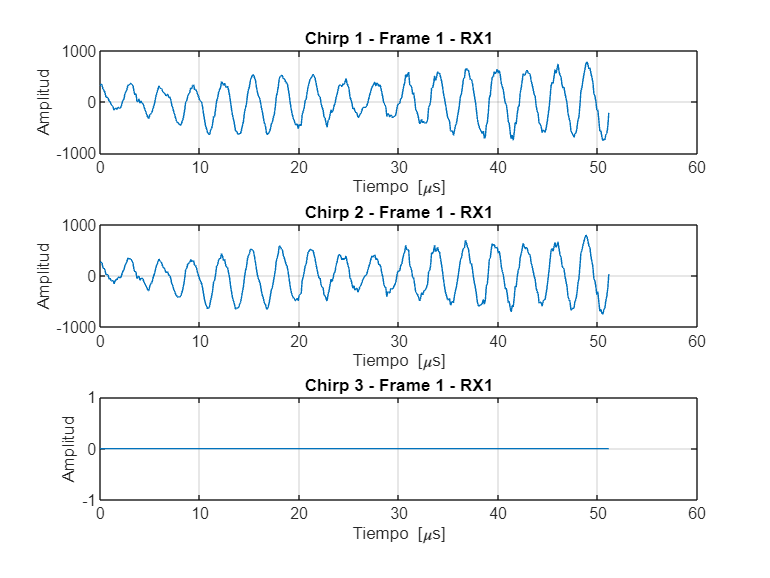

maximo_chirp = zeros(1,N_chirps);

for k = 1:N_chirps

    chirp = RX1_3D(:,k,1);

    maximo_chirp(k) = max(abs(chirp));

end

figure;


stem(1:N_chirps,maximo_chirp);

grid on;
xlabel('Número de chirp');
ylabel('Máxima magnitud');
title('Verificación de los 128 chirps - Frame 1');

Graficamente observamos que solo el chirp 3 es el nulo, para estar 100% seguros:

chirps_nulos = find(maximo_chirp == 0);

disp('Chirps completamente nulos en el Frame 1:');
disp(chirps_nulos);

Se encontró que únicamente el chirp 3 presenta todas sus muestras iguales a cero, mientras que los otros 127 chirps contienen información válida

## 7.4 Control de integridad de toda la adquisición

En esta seccion se hara la verificacion de los 128 x 400 chirps = 51200 chirps en total , necesitamos saber cuántos de esos 51 200 chirps están completamente en cero.

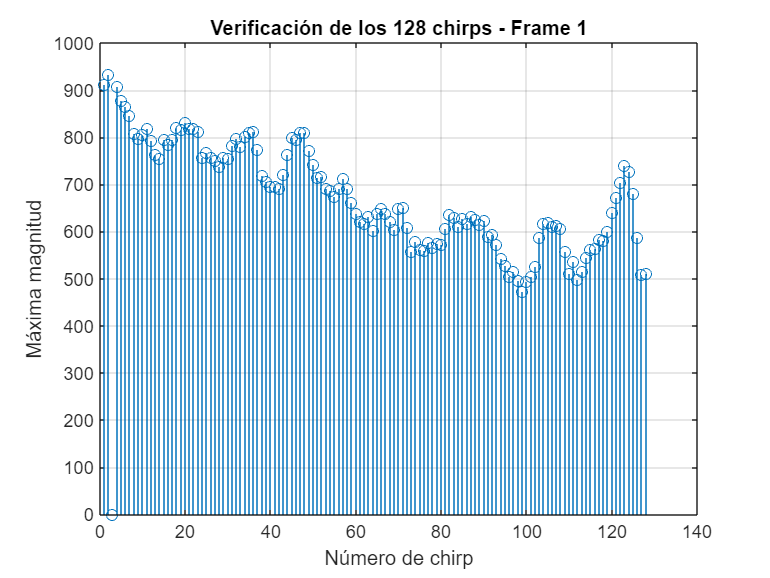

chirps_nulos_por_frame = zeros(1,N_frames);

for m = 1:N_frames


    contador = 0;

    for k = 1:N_chirps

        chirp = RX1_3D(:,k,m);

Chirps completamente nulos en el Frame 1:


     3



        if max(abs(chirp)) == 0
            contador = contador + 1;
        end

    end

    chirps_nulos_por_frame(m) = contador;

end

total_chirps_nulos = sum(chirps_nulos_por_frame);

disp("Número total de chirps nulos = " + num2str(total_chirps_nulos));
frames_con_nulos = find(chirps_nulos_por_frame > 0);

disp("Frames que contienen chirps nulos:");
disp(frames_con_nulos);
cantidad_nulos = chirps_nulos_por_frame(frames_con_nulos);

resultado_nulos = table(frames_con_nulos', cantidad_nulos','VariableNames', {'Frame','Chirps_nulos'});

disp(resultado_nulos);

Durante la verificación de integridad de la adquisición se analizaron los 51 200 chirps correspondientes a los 400 frames de RX1. Se detectaron solamente 11 chirps completamente nulos. Estos se encuentran concentrados exclusivamente en los primeros 10 frames: el frame 2 contiene dos chirps nulos y los frames 1,3,4,5,6,7,8,9 y 10 contienen uno cada uno. A partir del frame 11 no se detectaron chirps completamente nulos. Debido a que el posterior análisis Doppler depende de la continuidad temporal entre chirps, se decidió no eliminar chirps individuales ni generar datos artificiales mediante interpolación, para esta adquisición se utilizarán los frames 11 a 400, conservando 390 de los 400 frames originales, es decir, el 97.5 % de la adquisición. 

## 8. Preparación de la señal antes de la FFT de rango

Antes de aplicar la FFT a los 128 chirps de un frame, conviene preparar las 512 muestras de cada chirp para reducir dos efectos que pueden dificultar la interpretación del espectro.

Para elo validaremos dos conceptos, la componenten continua y la fuga espectral.

La eliminacion de la componente continua es para que el chirp quede aproximadamente centrado alrededor de cero.

RX1_valido = RX1_3D(:,:,11:400);
chirp = RX1_valido(:,1,1);


Número total de chirps nulos = 11


promedio_chirp = mean(chirp);

chirp_sinDC = chirp - promedio_chirp;

Frames que contienen chirps nulos:


     1     2     3     4     5     6     7     8     9    10



disp("Promedio antes de eliminar DC:");
disp(promedio_chirp);

Las componentes I y Q no estaban perfectamente centradas en cero.

disp("Promedio después de eliminar DC:");
disp(mean(chirp_sinDC));

La resta es 0 exacto.

## 8.1 Aplicación de la ventana Hann

Cuando hacemos una FFT de un chirp usamos únicamente sus 512 muestras

Es decir, estamos tomando un fragmento finito de la señal, se sabe que cuando una frecuencia no coincide exactamente con uno de los bins de la FFT, su energía puede repartirse entre bins vecinos. Ese fenómeno se denomina **fuga espectral**.

w = hann(N);

    Frame    Chirps_nulos
    _____    ____________

      1           1      
      2           2      
      3           1      
      4           1      
      5           1      
      6           1      
      7           1      
      8           1      
      9           1      
     10           1      



chirp_ventana = chirp_sinDC .* w;
figure;

subplot(3,1,1);
plot(t*1e6,real(chirp));
grid on;
xlabel('Tiempo [\mus]');
ylabel('Amplitud');
title('Chirp original');

subplot(3,1,2);
plot(t*1e6,real(chirp_sinDC));
grid on;
xlabel('Tiempo [\mus]');

Promedio antes de eliminar DC:


ylabel('Amplitud');

   5.4102 - 7.4727i



title('Chirp después de eliminar DC');

subplot(3,1,3);

Promedio después de eliminar DC:


plot(t*1e6,real(chirp_ventana));

     0



grid on;
xlabel('Tiempo [\mus]');
ylabel('Amplitud');
title('Chirp después de aplicar ventana Hann');

Como se observa en la figura, la ventana disminuye progresivamente la señal hacia ambos extremos del chirp, manteniendo mayor peso en la zona central. Esta operación se realiza antes de la FFT con el objetivo de reducir la fuga espectral producida al analizar un bloque finito de muestras. La ventana no elimina el ruido ni incrementa la resolución de frecuencia, sino que reduce la dispersión de energía hacia bins vecinos.

Ahora si ya podemos decir que tenemos el chirp preparado para aplicarle la FFT.

## 9. FFT de rango para los 128 chirps de un frame

Hasta ahora aplicamos la FFT solamente a un chirp de 512 muestras y encontramos una frecuencia beat dominante.

Ahora queremos hacer exactamente lo mismo, pero para **cada uno de los 128 chirps de un frame**. Al juntar los 128 resultados tendremos una matriz que nos dirá: **qué reflexiones aparecen a cada distancia y cómo cambian de un chirp al siguiente.**

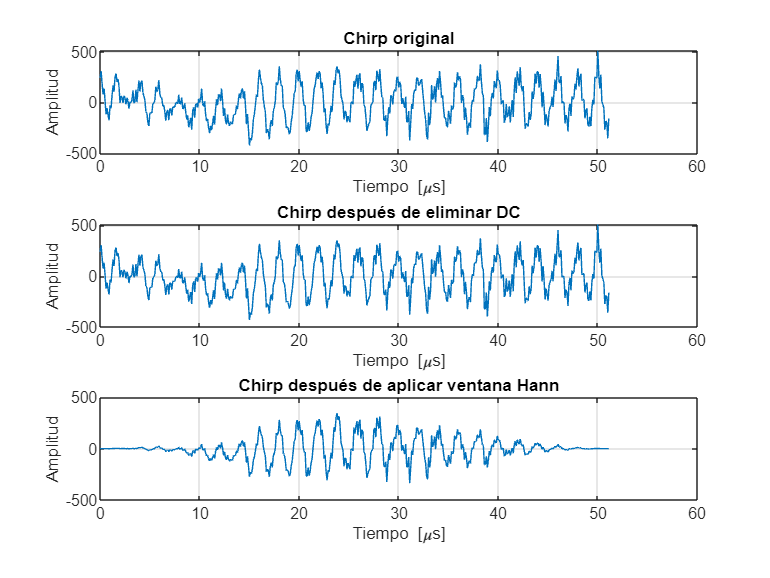

frame = RX1_valido(:,:,1);

range_fft = zeros(N,N_chirps);

w = hann(N);

for k = 1:N_chirps

    chirp = frame(:,k);

    chirp_sinDC = chirp - mean(chirp);

    chirp_ventana = chirp_sinDC .* w;

    X = fft(chirp_ventana);

    range_fft(:,k) = fftshift(X);

end


f = (-N/2:N/2-1)*(Fs/N);
idx_neg = N/2+1:-1:1;


f_beat = abs(f(idx_neg));

range_neg = range_fft(idx_neg,:);
R_axis = c*f_beat/(2*S);
figure;

imagesc(1:N_chirps,R_axis,abs(range_neg));

axis xy;
colorbar;

xlabel('Número de chirp');
ylabel('Distancia [m]');
title('Mapa rango-chirp - Frame válido 1 - RX1');

El mapa rango–chirp representa los perfiles de rango correspondientes a los 128 chirps del primer frame válido. Se observa una reflexión dominante aproximadamente alrededor de 1–1.5 m, la cual permanece en una posición de rango similar durante prácticamente todo el frame. También aparecen otras reflexiones de menor magnitud a diferentes distancias, destacando una componente alrededor de 8.5–9 m. La presencia de bandas aproximadamente horizontales indica reflexiones cuya distancia cambia poco entre chirps consecutivos.

Por qué muchas líneas son horizontales? Esta reflexión aparece en la misma distancia durante muchos chirps , puede ser algo estatico presente durante la toma de datos.

## 10. Filtro MTI: reducción de reflexiones estáticas

En el Paso 9 obtuvimos el mapa rango–chirp y observamos varias bandas que permanecían prácticamente en la misma distancia durante los 128 chirps.

Eso puede ocurrir porque el radar no recibe solamente el eco de la persona. También recibe reflexiones de paredes, piso, muebles, estructuras, etc, cosas que estan estaticas practicamente, ya tenemos range_neg, que tiene dimensiones de 256x128, cada **fila** representa una determinada distancia, entonces, para cada distancia, tenemos 128 valores complejos, calcularemos su promedio:


$$\textrm{Xprom}=\frac{\left(\textrm{x1}+\textrm{x2}+\textrm{x3}+\textrm{x4}+\ldotp 
\ldotp \ldotp \ldotp \textrm{x128}\right)}{128}$$


Ese promedio representa aproximadamente la parte que permanece constante a lo largo de los chirps, para despues hacer XMTI[k]= x[k]-Xprom

promedio_rango = mean(range_neg,2);

range_mti = range_neg - promedio_rango;
%Para cada fila de distancia, promedia los 128 chirps.

El mapa rango–chirp obtenido anteriormente contiene tanto reflexiones producidas por objetos en movimiento como componentes asociadas a elementos estáticos del entorno. Estas últimas pueden presentar una magnitud elevada y dificultar la observación del movimiento humano. Para atenuarlas se utiliza un esquema MTI sencillo basado en sustracción de media. Se calcula el promedio complejo de la respuesta a lo largo de los 128 chirps del frame. Este promedio representa la componente que permanece aproximadamente constante durante el intervalo observado y posteriormente se resta de cada chirp.Comparemos antes y despues del filtro

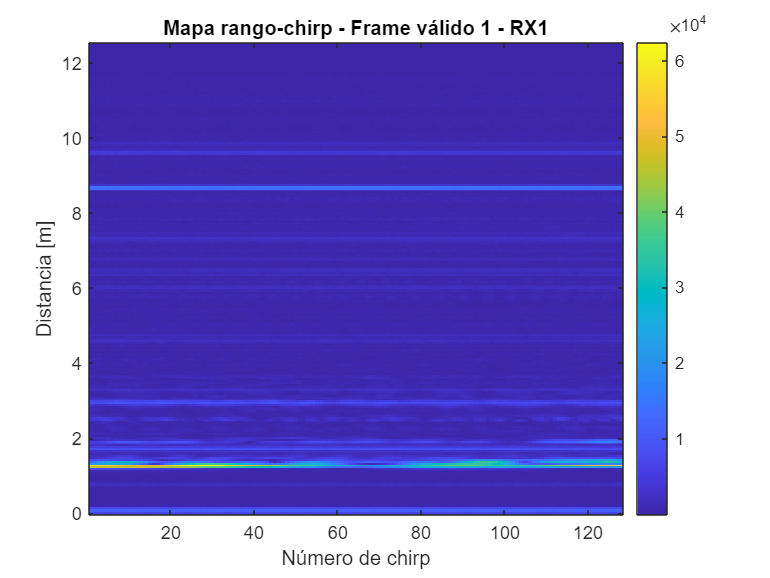

magnitud_antes = abs(range_neg);
magnitud_despues = abs(range_mti);

limite_color = max(magnitud_antes(:));

figure;

subplot(1,2,1);

imagesc(1:N_chirps,R_axis,magnitud_antes);

axis xy;

colorbar;
clim([0 limite_color]);

xlabel('Número de chirp');
ylabel('Distancia [m]');
title('Antes del MTI');


subplot(1,2,2);

imagesc(1:N_chirps,R_axis,magnitud_despues);

axis xy;
colorbar;
clim([0 limite_color]);

xlabel('Número de chirp');
ylabel('Distancia [m]');
title('Después del MTI');

La comparación antes y después del filtro MTI muestra una reducción significativa de varias componentes que permanecían prácticamente constantes a lo largo de los 128 chirps. Este efecto es especialmente visible en la reflexión ubicada aproximadamente entre 8.5 y 9 m, así como en distintas componentes presentes entre 2 y 4 m, cuya magnitud disminuye considerablemente después de la sustracción de media.

Por otro lado, una reflexión intensa ubicada aproximadamente entre 1 y 1.5 m permanece visible después del MTI. Esto indica que dicha componente no es completamente constante entre chirps, sino que presenta variaciones de amplitud y/o fase. Estas variaciones pueden estar asociadas a un reflector dinámico y constituyen la información de interés para el posterior análisis Doppler. En esta etapa todavía no se identifica directamente dicha reflexión con la persona.

## 11. Análisis Doppler mediante una segunda FFT

Hasta este momento ya hicimos tres cosas importantes:

FFT de rango para saber a que distancia aparecen las reflexiones.

MTI para reducir muchas reflexiones que permanecian estaticas

Ahora queremos saber si las reflexiones que quedaron están cambiando de un chirp al siguiente, ese cambio entre chirps contiene información relacionada con el movimiento. Sabemos que una FFT sirve para encontrar qué frecuencias existen dentro de una secuencia, con la primera hicimos esto: 

- 512 muestras - FFT - frecuencia de beat - distancia

Ahora la nueva frecuencia sera

- 128 chirps - FFT - Frecuencia doppler

FFT sobre chirps para saber el doppler. La frecuencia Doppler nos dice qué tan rápido está cambiando la señal de un chirp al siguiente.

N_rangos = size(range_mti,1);

doppler_fft = zeros(N_rangos,N_chirps);

for r = 1:N_rangos

    senal_chirps = range_mti(r,:);

    D = fft(senal_chirps);

    doppler_fft(r,:) = fftshift(D);

end

Preparamos magnitud para visualizarla

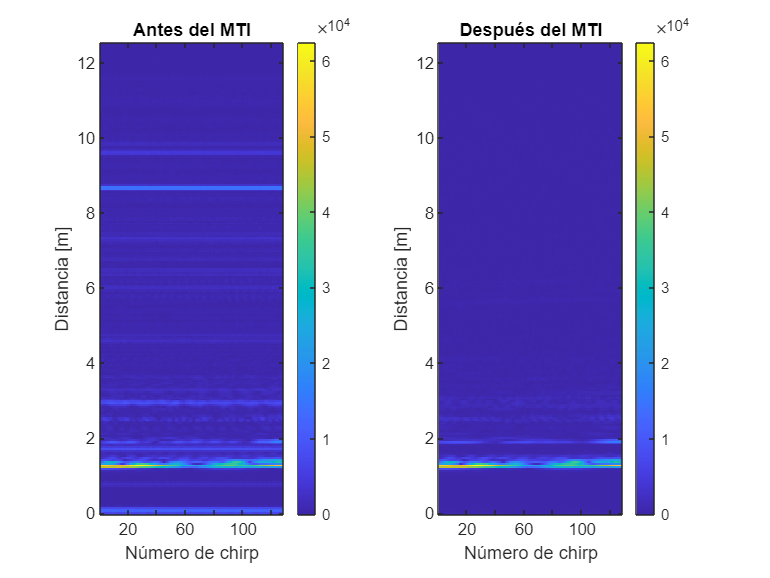

fD_norm = (-N_chirps/2:N_chirps/2-1)/N_chirps; %eje dopler
D_mag = abs(doppler_fft);
D_norm = D_mag/max(D_mag(:));
D_dB = 20*log10(D_norm + eps);
figure;

imagesc(fD_norm,R_axis,D_dB);

axis xy;
colorbar;


clim([-60 0]);

xlabel('Frecuencia Doppler normalizada [ciclos/chirp]');
ylabel('Distancia [m]');
title('Mapa rango-Doppler - RX1');

Después de obtener la información de rango y reducir las componentes estáticas mediante MTI, se busca analizar cómo cambia la señal entre chirps consecutivos. Para cada distancia se dispone de 128 valores complejos correspondientes a los 128 chirps de un frame. Si existe movimiento, estos valores presentan variaciones entre chirps, especialmente en su fase.

Para estudiar dichas variaciones se aplica nuevamente una FFT, pero esta vez sobre la dimensión de los chirps. La primera FFT se realizó sobre las 512 muestras de cada chirp para obtener información de rango; la segunda FFT se realiza sobre los 128 chirps para obtener información Doppler.

El resultado se representa mediante un mapa rango–Doppler, donde el eje vertical indica distancia y el eje horizontal representa la frecuencia Doppler. En esta primera etapa el Doppler se expresa de manera normalizada en ciclos por chirp. Posteriormente se podrá convertir a velocidad radial utilizando los parámetros temporales del radar.

En el mapa podemos observar que la mayor concentración de energía se encuentra aproximadamente entre 1 y 3 m, principalmente en la zona de Doppler negativo. Además, la señal más intensa se presenta alrededor de 1 a 1.5 m. A diferencia del mapa rango–chirp, donde solo podíamos ver cómo cambiaban las señales reflejadas entre un chirp y otro, con la segunda FFT podemos observar estos cambios en términos de frecuencia Doppler, lo que nos ayuda a identificar el movimiento del objeto. También podemos notar que la energía no se concentra en un solo punto, sino que está distribuida en una región. Esto puede deberse a que el objeto, en este caso una persona caminando, tiene diferentes partes del cuerpo que se mueven a distintas velocidades, como los brazos y las piernas. Por último, este análisis corresponde únicamente a un frame, por lo que todavía no podemos observar cómo cambia el movimiento durante toda la caminata. Para ello, será necesario analizar varios frames y así obtener una representación micro-Doppler que nos permita estudiar mejor estos movimientos a lo largo del tiempo.

## 12. Conversión de Doppler a velocidad radial

En el Paso 11 nuestro mapa tiene en el eje horizontal ciclos/chirp, pero es mas util usar m/s. El radar mide especialmente el movimiento hacia el radar o alejandose del radar,si la persona se acerca o se aleja, produce Doppler. Segun las caracteristicas leidas, el tiempo entre chirps es t= 160 us, esos parámetros vienen de la configuración original del dataset eso significa que el radar genera 6250 chirps/s , entonces Fchirp seria 6250 Hz.

Ahora bien, calculando la longitud de onda hacemos uso de :


$$\textrm{lambda}=\frac{c}{\textrm{fc}}$$


fc=77 GHz

lambda=3.9 mm

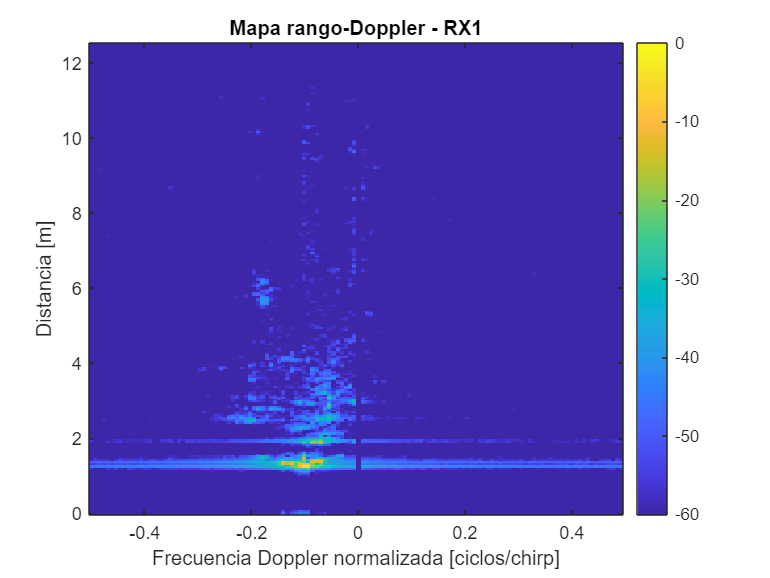

t_idle = 100e-6;
t_ramp = 60e-6;

T_chirp = t_idle + t_ramp;

F_chirp = 1/T_chirp;

fc = 77e9;

lambda = c/fc;

fD = fD_norm*F_chirp;

v_axis = lambda*fD/2;
disp("Tiempo entre chirps [us]:");
disp(T_chirp*1e6);

disp("Chirps por segundo:");
disp(F_chirp);

disp("Longitud de onda aproximada [mm]:");
disp(lambda*1000);

figure;

imagesc(v_axis,R_axis,D_dB);

axis xy;
colorbar;

clim([-60 0]);


xlabel('Velocidad radial [m/s]');
ylabel('Distancia [m]');
title('Mapa rango-velocidad - RX1');

El resultado de la segunda FFT se obtuvo inicialmente en frecuencia Doppler normalizada, expresada en ciclos por chirp. Para facilitar su interpretación física, esta frecuencia se convierte a velocidad radial. La configuración del dataset establece un tiempo de 100 µs de espera y 60 µs de rampa, por lo que el intervalo entre chirps es de 160 µs, equivalente a una repetición de aproximadamente 6250 chirps por segundo.

A partir de este intervalo se convierte la frecuencia Doppler normalizada a Hz. Posteriormente se utiliza la longitud de onda del radar, aproximadamente 3.9 mm empleando 77 GHz como frecuencia nominal de referencia, para convertir la frecuencia Doppler en velocidad radial. De esta manera, el mapa rango–Doppler puede representarse utilizando distancia en metros y velocidad radial en m/s, facilitando posteriormente la comparación entre caminatas.

## 13 Repetir el procesamiento en todos los frames

Creamos primero una matriz donde guardaremos el resultado.

N_frames_validos = size(RX1_valido,3);

microDoppler = zeros(N_chirps,N_frames_validos);

for m = 1:N_frames_validos
    frame = RX1_valido(:,:,m);
    range_fft_frame = zeros(N,N_chirps);

    for k = 1:N_chirps

        chirp = frame(:,k);
        chirp_sinDC = chirp - mean(chirp);
        chirp_ventana = chirp_sinDC .* w;
        X = fft(chirp_ventana);


Tiempo entre chirps [us]:


        range_fft_frame(:,k) = fftshift(X);

   160




    end

Chirps por segundo:


   6.2500e+03



    % Nos quedamos con la zona de beat utilizada anteriormente
    range_frame = range_fft_frame(idx_neg,:);

Longitud de onda aproximada [mm]:


    3.8961



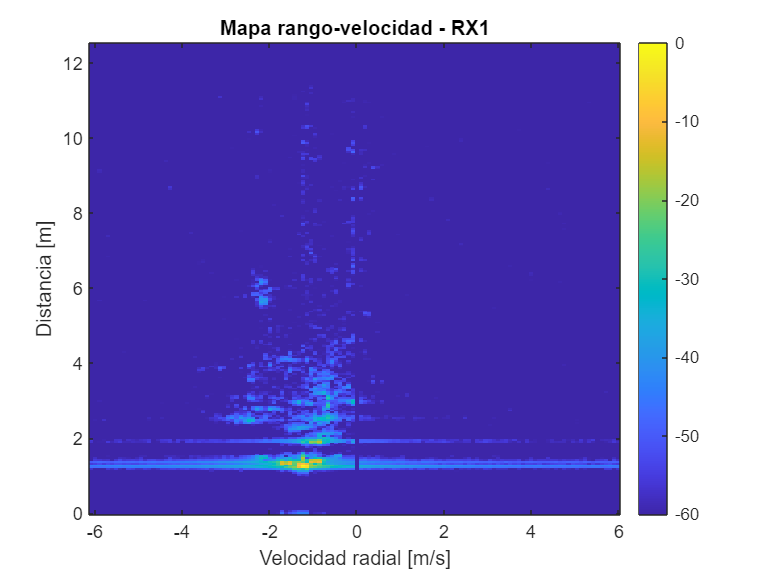

    promedio_frame = mean(range_frame,2);

    range_frame_mti = range_frame - promedio_frame;

    doppler_frame = zeros(size(range_frame_mti));

    for r = 1:size(range_frame_mti,1)

        D = fft(range_frame_mti(r,:));

        doppler_frame(r,:) = fftshift(D);

    end


    perfil_doppler = max(abs(doppler_frame),[],1);

    microDoppler(:,m) = perfil_doppler.';

end

micro_mag = abs(microDoppler);

micro_norm = micro_mag/max(micro_mag(:));

micro_dB = 20*log10(micro_norm + eps);
figure;

imagesc(1:N_frames_validos,v_axis,micro_dB);

axis xy;
colorbar;

clim([-60 0]);

xlabel('Número de frame');
ylabel('Velocidad radial [m/s]');
title('Mapa micro-Doppler - Fast - RX1');

Al observar el mapa micro-Doppler, podemos notar que durante los primeros 120 a 140 frames la mayor concentración de energía se encuentra en velocidades negativas, aproximadamente entre -1 y -2 m/s. Esto nos indica que, al inicio del experimento, la persona presenta un movimiento predominante en una dirección respecto al radar. Sin embargo, no podemos asegurar si se está acercando o alejando, ya que esto depende de cómo se haya definido el signo de la velocidad durante el procesamiento.

Entre los frames 130 y 150 observamos que la velocidad se acerca a cero. Esto podría indicar que la persona está pasando por una posición donde su movimiento en dirección al radar disminuye. Es importante tener en cuenta que esto no significa necesariamente que la persona se haya detenido, ya que puede seguir caminando, pero en una dirección más perpendicular al radar.

Después del frame 150, la mayor concentración de energía comienza a aparecer en velocidades positivas, aproximadamente entre 1 y 2 m/s, y se mantiene hasta los frames 280 a 300. Este cambio de velocidades negativas a positivas nos sugiere que la persona ha cambiado el sentido de su movimiento respecto al radar. Por ejemplo, podría estar caminando de un lado hacia otro, pasando frente al radar. Sin embargo, con esta gráfica no podemos determinar exactamente la trayectoria que siguió.

También podemos observar que la energía no aparece como una línea delgada, sino como una banda con pequeñas variaciones a su alrededor, especialmente entre los frames 160 y 270. Esto ocurre porque una persona no se mueve como un solo bloque. Mientras el torso mantiene un movimiento más uniforme, los brazos y las piernas se mueven a diferentes velocidades durante cada paso. Estas pequeñas variaciones son las que forman parte del **efecto micro-Doppler**, que nos permite identificar características del movimiento de una persona.

A partir del frame 300, observamos que la energía relacionada con el movimiento disminuye considerablemente. Esto podría deberse a que la persona salió de la zona de detección del radar o a que sus movimientos dejaron de producir señales suficientemente intensas. Sin embargo, no podemos determinar la causa exacta únicamente con esta gráfica.

Por último, también se observan algunas franjas verticales más brillantes en determinados frames. Estas indican que, en esos instantes, aparece energía distribuida en un rango más amplio de velocidades. Esto podría estar relacionado con movimientos rápidos de algunas partes del cuerpo o con efectos del procesamiento de las señales.

En general, **el mapa micro-Doppler nos permite observar cómo cambia el movimiento de la persona a lo largo del tiempo**, identificando variaciones en la velocidad y posibles movimientos de los brazos y las piernas durante la caminata.

## 13. Verificación de los cuatro receptores y detección de chirps nulos

Hasta este punto se desarrolló y verificó el procesamiento utilizando únicamente el receptor RX1. Sin embargo, el archivo de adquisición contiene cuatro canales receptores: RX1, RX2, RX3 y RX4.

Antes de utilizar conjuntamente los cuatro receptores, se verificará que sus datos sean válidos. En particular, se buscarán chirps completamente nulos, es decir, chirps cuyas 512 muestras tengan valor cero.

Esta verificación es importante porque los cuatro receptores fueron adquiridos al mismo tiempo y deben mantenerse sincronizados. Por ello, primero se identificarán los posibles frames con datos nulos y posteriormente se decidirá qué frames utilizar en común para los cuatro canales.

## 13. Verificacion de los cuatro receptores y chirps nulos

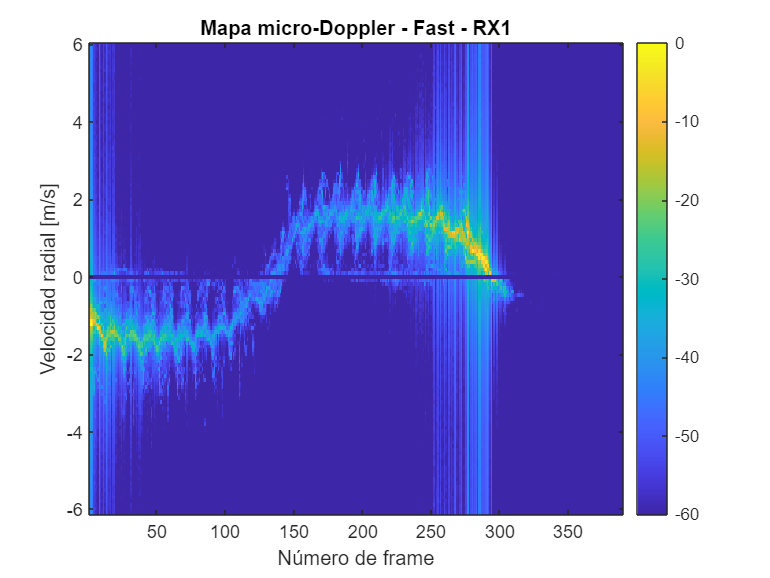

% Parametros de la adquisicion
N_muestras = 512;
N_chirps = 128;
N_frames = 400;

% Extraemos los cuatro receptores de la tabla
RX1 = adc_DataTable.adc_DataRX1;
RX2 = adc_DataTable.adc_DataRX2;
RX3 = adc_DataTable.adc_DataRX3;
RX4 = adc_DataTable.adc_DataRX4;

% Organizamos cada receptor:
% muestras x chirps x frames
RX1_3D = reshape(RX1,N_muestras,N_chirps,N_frames);
RX2_3D = reshape(RX2,N_muestras,N_chirps,N_frames);
RX3_3D = reshape(RX3,N_muestras,N_chirps,N_frames);
RX4_3D = reshape(RX4,N_muestras,N_chirps,N_frames);


% Cada columna corresponde a un receptor
nulos_por_frame = zeros(N_frames,4);

% Revisamos todos los frames y todos los chirps
for m = 1:N_frames

    for k = 1:N_chirps

        if max(abs(RX1_3D(:,k,m))) == 0
            nulos_por_frame(m,1) = nulos_por_frame(m,1) + 1;
        end

        if max(abs(RX2_3D(:,k,m))) == 0
            nulos_por_frame(m,2) = nulos_por_frame(m,2) + 1;
        end

        if max(abs(RX3_3D(:,k,m))) == 0
            nulos_por_frame(m,3) = nulos_por_frame(m,3) + 1;
        end

        if max(abs(RX4_3D(:,k,m))) == 0
            nulos_por_frame(m,4) = nulos_por_frame(m,4) + 1;
        end

    end
end

Cuantos chirps nulos tiene cada receptor:

## Resumen de chirps nulos

total_chirps = N_frames*N_chirps;

totales_nulos = sum(nulos_por_frame,1);

porcentaje_nulos = 100*totales_nulos/total_chirps;

porcentaje_validos = 100 - porcentaje_nulos;

receptor = ["RX1";"RX2";"RX3";"RX4"];

tabla_resumen = table(receptor,totales_nulos.',porcentaje_nulos.',porcentaje_validos.','VariableNames',{'Receptor','Chirps_nulos','Porcentaje_nulos','Porcentaje_validos'});

disp(tabla_resumen);

Ahora para saber en eu frames estan los chirps vacios:

## Frames que presentan chirps nulos

frames_RX1 = find(nulos_por_frame(:,1) > 0);
frames_RX2 = find(nulos_por_frame(:,2) > 0);
frames_RX3 = find(nulos_por_frame(:,3) > 0);
frames_RX4 = find(nulos_por_frame(:,4) > 0);

disp('Frames con chirps nulos en RX1:');
disp(frames_RX1.');

disp('Frames con chirps nulos en RX2:');
disp(frames_RX2.');

disp('Frames con chirps nulos en RX3:');
disp(frames_RX3.');

    Receptor    Chirps_nulos    Porcentaje_nulos    Porcentaje_validos
    ________    ____________    ________________    __________________

     "RX1"           11             0.021484              99.979      
     "RX2"           10             0.019531               99.98      
     "RX3"           10             0.019531               99.98      
     "RX4"           10             0.019531               99.98      




disp('Frames con chirps nulos en RX4:');
disp(frames_RX4.');

## 14. Selección común de frames válidos para los cuatro receptores

La verificación de los cuatro receptores mostró que los chirps completamente nulos se encuentran únicamente dentro de los primeros 10 frames de la adquisición. RX1 presentó 11 chirps nulos, mientras que RX2, RX3 y RX4 presentaron 10 cada uno.

Debido a que todos los problemas se encuentran concentrados en los mismos primeros 10 frames, se utilizarán los frames 11 al 400 para los cuatro receptores. De esta manera se conserva la sincronización temporal entre RX1, RX2, RX3 y RX4 y se evita modificar o interpolar datos faltantes.

RX1_valido = RX1_3D(:,:,11:400);
RX2_valido = RX2_3D(:,:,11:400);
RX3_valido = RX3_3D(:,:,11:400);
RX4_valido = RX4_3D(:,:,11:400);

N_frames_validos = size(RX1_valido,3);

Frames con chirps nulos en RX1:


     1     2     3     4     5     6     7     8     9    10



disp('Numero de frames validos:');
disp(N_frames_validos);

Frames con chirps nulos en RX2:


## 15. Procesamiento conjunto de los cuatro receptores y mapa micro-Doppler combinado

Una vez seleccionados los frames válidos comunes, se aplica el mismo procesamiento a los cuatro receptores RX1, RX2, RX3 y RX4.

Cada receptor se procesa independientemente mediante eliminación de DC, ventana Hann, FFT de rango, MTI y FFT Doppler. Después de obtener el resultado Doppler de cada receptor, se combinan sus potencias.

La combinación se realiza después del procesamiento debido a que las señales de los cuatro receptores pueden presentar diferencias de fase. Si las señales complejas se sumaran directamente, algunas componentes podrían cancelarse. Al combinar las potencias se aprovecha la información recibida por los cuatro canales sin realizar una combinación de fase.

## 15. Procesamiento conjunto de los cuatro receptores

% Matriz donde guardaremos el resultado final

     1     2     3     4     5     6     7     8     9    10



microDoppler_4RX = zeros(N_chirps,N_frames_validos);


Frames con chirps nulos en RX3:


% Numero de bins de rango que utilizaremos

     1     2     3     4     5     6     7     8     9    10



N_rangos = length(idx_neg);


Frames con chirps nulos en RX4:


for m = 1:N_frames_validos

     1     2     3     4     5     6     7     8     9    10




    % Aqui acumularemos la potencia de los 4 receptores
    potencia_combinada = zeros(N_rangos,N_chirps);

    % Procesamos RX1, RX2, RX3 y RX4
    for rx = 1:4

        % Seleccionamos el mismo frame del receptor actual
        if rx == 1
            frame = RX1_valido(:,:,m);
        elseif rx == 2
            frame = RX2_valido(:,:,m);

Numero de frames validos:


        elseif rx == 3

   390



            frame = RX3_valido(:,:,m);
        else
            frame = RX4_valido(:,:,m);
        end

        % Matriz para guardar la FFT de rango
        range_fft_frame = zeros(N,N_chirps);

        % ----- FFT DE RANGO -----
        for k = 1:N_chirps

            chirp = frame(:,k);

            % Eliminacion de DC
            chirp_sinDC = chirp - mean(chirp);

            % Ventana Hann
            chirp_ventana = chirp_sinDC .* w;

            % FFT de rango
            X = fft(chirp_ventana);

            range_fft_frame(:,k) = fftshift(X);

        end

        % Seleccionamos el lado utilizado de la FFT
        range_frame = range_fft_frame(idx_neg,:);

        % ----- MTI -----
        promedio_rango = mean(range_frame,2);

        range_frame_mti = range_frame - promedio_rango;

        % ----- FFT DOPPLER -----
        doppler_frame = zeros(size(range_frame_mti));

        for r = 1:N_rangos

            D = fft(range_frame_mti(r,:));

            doppler_frame(r,:) = fftshift(D);

        end

        % Potencia Doppler del receptor actual
        potencia_rx = abs(doppler_frame).^2;

        % Sumamos la potencia del receptor
        potencia_combinada = potencia_combinada + potencia_rx;

    end

    % Promedio de potencia de los cuatro receptores
    potencia_combinada = potencia_combinada/4;

    % Para cada velocidad tomamos la reflexion mas fuerte
    % entre todas las distancias
    perfil_doppler = max(potencia_combinada,[],1);

    % Guardamos el perfil correspondiente a este frame
    microDoppler_4RX(:,m) = perfil_doppler.';

end

## Conversion del resultado combinado a dB

micro_norm_4RX = microDoppler_4RX/max(microDoppler_4RX(:));

micro_dB_4RX = 10*log10(micro_norm_4RX + eps);

## Mapa micro-Doppler combinado de los cuatro receptores

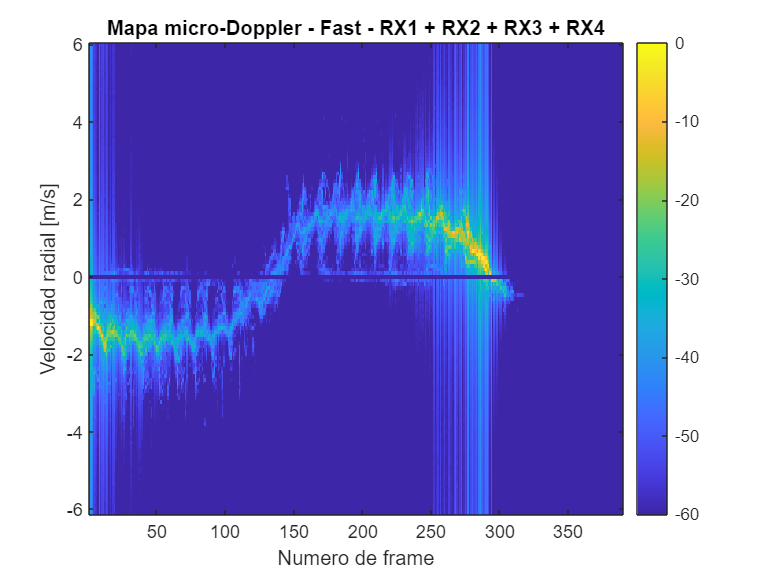

figure;

imagesc(1:N_frames_validos,v_axis,micro_dB_4RX);

axis xy;
colorbar;

clim([-60 0]);

xlabel('Numero de frame');
ylabel('Velocidad radial [m/s]');

title('Mapa micro-Doppler - Fast - RX1 + RX2 + RX3 + RX4');

El mapa micro-Doppler combinado de los cuatro receptores conserva el comportamiento general observado previamente con RX1. Durante los primeros frames la energía se concentra principalmente en velocidades radiales negativas, posteriormente se aproxima a velocidad cero y finalmente aparece en velocidades radiales positivas. Esto muestra que el cambio de signo observado anteriormente no corresponde únicamente a un canal receptor, sino que también está presente al considerar conjuntamente la información de RX1, RX2, RX3 y RX4.

## Mapa micro-Doppler combinado de los 4 RX con eje de tiempo

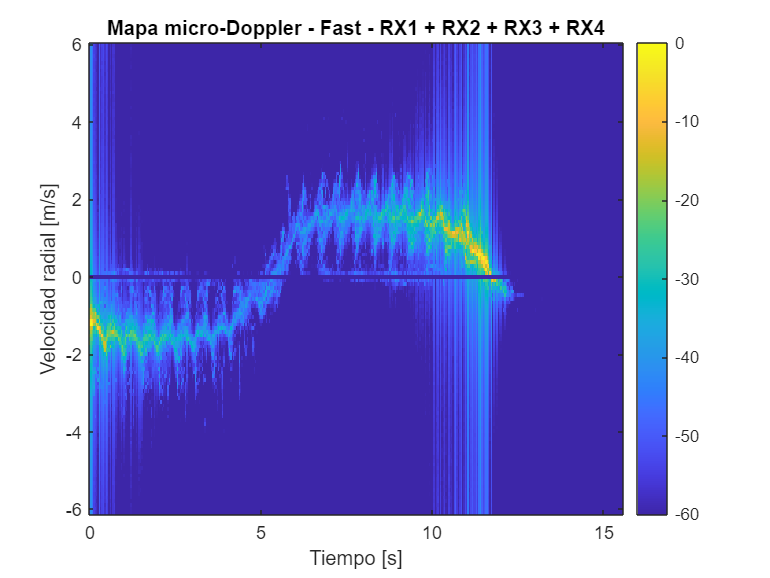

T_frame = 40e-3;   % Periodo entre frames = 40 ms

% Tiempo relativo desde el primer frame valido
t_frames = (0:N_frames_validos-1)*T_frame;

figure;

imagesc(t_frames,v_axis,micro_dB_4RX);

axis xy;
colorbar;
clim([-60 0]);

xlabel('Tiempo [s]');
ylabel('Velocidad radial [m/s]');
title('Mapa micro-Doppler - Fast - RX1 + RX2 + RX3 + RX4');


micro_dB_Fast = micro_dB_4RX;

## 16. Procesamiento de Caminata Lenta (Slow) y mapa micro-Doppler combinado

Se procesa el archivo de datos local de la caminata lenta (Slow_part1) aplicando el mismo flujo: eliminación de continua por chirp, ventana Hann, FFT de rango, filtrado MTI, FFT Doppler y combinación no coherente de potencia de los cuatro canales receptores (RX1 a RX4).

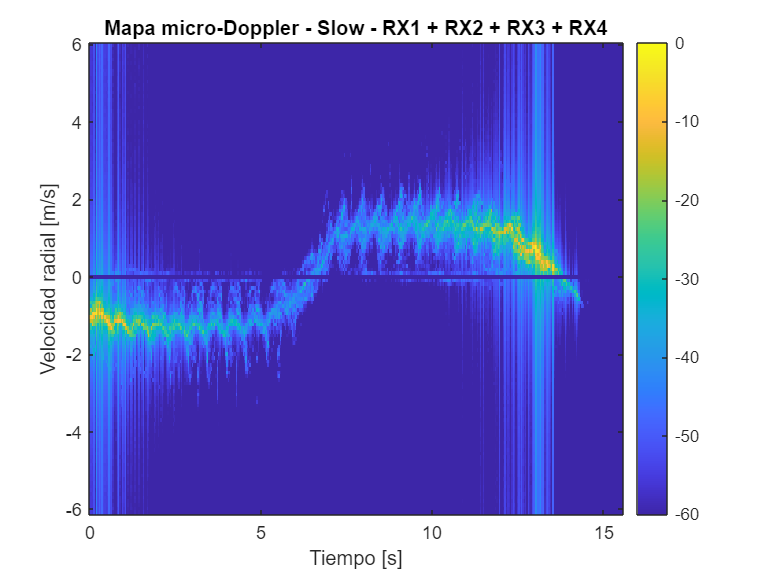

dataFile_Slow = fullfile("Slow_part1", "1", "adc_Data.mat");
if ~isfile(dataFile_Slow) && isfile(fullfile("PSID-RADAR", dataFile_Slow))
    dataFile_Slow = fullfile("PSID-RADAR", dataFile_Slow);
end
data_Slow = load(dataFile_Slow);
t_Slow = data_Slow.adc_DataTable;

% Organización de los 4 receptores y selección de frames válidos (11:400)
RX1_Slow = reshape(t_Slow.adc_DataRX1, N_muestras, N_chirps, N_frames);
RX2_Slow = reshape(t_Slow.adc_DataRX2, N_muestras, N_chirps, N_frames);
RX3_Slow = reshape(t_Slow.adc_DataRX3, N_muestras, N_chirps, N_frames);
RX4_Slow = reshape(t_Slow.adc_DataRX4, N_muestras, N_chirps, N_frames);

RX1_Slow_val = RX1_Slow(:,:,11:400);
RX2_Slow_val = RX2_Slow(:,:,11:400);
RX3_Slow_val = RX3_Slow(:,:,11:400);
RX4_Slow_val = RX4_Slow(:,:,11:400);

microDoppler_Slow = zeros(N_chirps, N_frames_validos);

for m = 1:N_frames_validos
    potencia_combinada = zeros(N_rangos, N_chirps);
    for rx = 1:4
        if rx == 1
            frame = RX1_Slow_val(:,:,m);
        elseif rx == 2
            frame = RX2_Slow_val(:,:,m);
        elseif rx == 3
            frame = RX3_Slow_val(:,:,m);
        else
            frame = RX4_Slow_val(:,:,m);
        end

        range_fft_frame = zeros(N_muestras, N_chirps);
        for k = 1:N_chirps
            chirp = frame(:,k);
            chirp_sinDC = chirp - mean(chirp);
            chirp_ventana = chirp_sinDC .* w;
            X = fft(chirp_ventana);
            range_fft_frame(:,k) = fftshift(X);
        end

        range_frame = range_fft_frame(idx_neg,:);
        promedio_rango = mean(range_frame,2);
        range_frame_mti = range_frame - promedio_rango;

        doppler_frame = zeros(size(range_frame_mti));
        for r = 1:N_rangos
            D = fft(range_frame_mti(r,:));
            doppler_frame(r,:) = fftshift(D);
        end

        potencia_rx = abs(doppler_frame).^2;
        potencia_combinada = potencia_combinada + potencia_rx;
    end
    potencia_combinada = potencia_combinada / 4;
    perfil_doppler = max(potencia_combinada, [], 1);
    microDoppler_Slow(:,m) = perfil_doppler.';
end

% Normalización a dB con rango dinámico [-60 0] dB
micro_norm_Slow = microDoppler_Slow / max(microDoppler_Slow(:));
micro_dB_Slow = 10 * log10(micro_norm_Slow + eps);

figure;
imagesc(t_frames, v_axis, micro_dB_Slow);
axis xy;
colorbar;
clim([-60 0]);
xlabel('Tiempo [s]');
ylabel('Velocidad radial [m/s]');
title('Mapa micro-Doppler - Slow - RX1 + RX2 + RX3 + RX4');

## 17. Procesamiento de Manos en Bolsillos (SlowPocket) y mapa micro-Doppler combinado

Se procesa el archivo de datos local de la caminata con manos en bolsillos (SlowPocket_part1) mediante el mismo procesamiento conjunto de los 4 canales receptores.

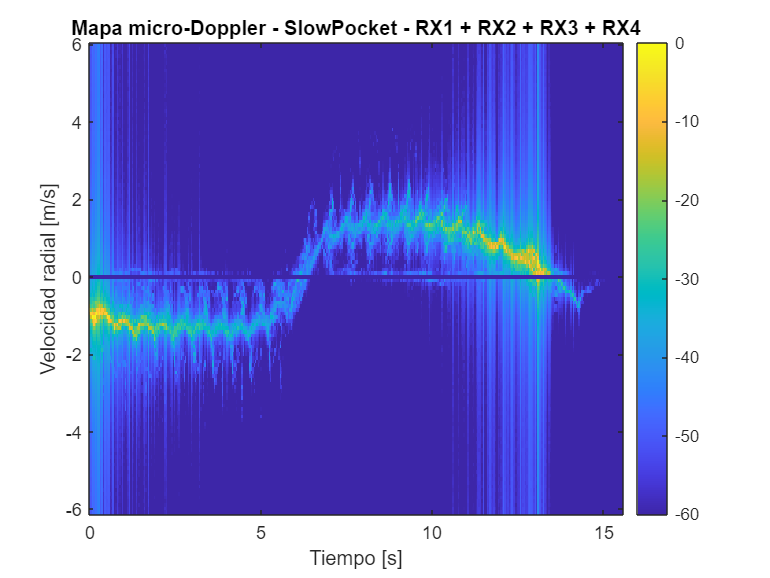

dataFile_SlowPocket = fullfile("SlowPocket_part1", "1", "adc_Data.mat");
if ~isfile(dataFile_SlowPocket) && isfile(fullfile("PSID-RADAR", dataFile_SlowPocket))
    dataFile_SlowPocket = fullfile("PSID-RADAR", dataFile_SlowPocket);
end
data_SlowPocket = load(dataFile_SlowPocket);
t_SlowPocket = data_SlowPocket.adc_DataTable;

% Organización de los 4 receptores y selección de frames válidos (11:400)
RX1_SlowPocket = reshape(t_SlowPocket.adc_DataRX1, N_muestras, N_chirps, N_frames);
RX2_SlowPocket = reshape(t_SlowPocket.adc_DataRX2, N_muestras, N_chirps, N_frames);
RX3_SlowPocket = reshape(t_SlowPocket.adc_DataRX3, N_muestras, N_chirps, N_frames);
RX4_SlowPocket = reshape(t_SlowPocket.adc_DataRX4, N_muestras, N_chirps, N_frames);

RX1_SlowPocket_val = RX1_SlowPocket(:,:,11:400);
RX2_SlowPocket_val = RX2_SlowPocket(:,:,11:400);
RX3_SlowPocket_val = RX3_SlowPocket(:,:,11:400);
RX4_SlowPocket_val = RX4_SlowPocket(:,:,11:400);

microDoppler_SlowPocket = zeros(N_chirps, N_frames_validos);

for m = 1:N_frames_validos
    potencia_combinada = zeros(N_rangos, N_chirps);
    for rx = 1:4
        if rx == 1
            frame = RX1_SlowPocket_val(:,:,m);
        elseif rx == 2
            frame = RX2_SlowPocket_val(:,:,m);
        elseif rx == 3
            frame = RX3_SlowPocket_val(:,:,m);
        else
            frame = RX4_SlowPocket_val(:,:,m);
        end

        range_fft_frame = zeros(N_muestras, N_chirps);
        for k = 1:N_chirps
            chirp = frame(:,k);
            chirp_sinDC = chirp - mean(chirp);
            chirp_ventana = chirp_sinDC .* w;
            X = fft(chirp_ventana);
            range_fft_frame(:,k) = fftshift(X);
        end

        range_frame = range_fft_frame(idx_neg,:);
        promedio_rango = mean(range_frame,2);
        range_frame_mti = range_frame - promedio_rango;

        doppler_frame = zeros(size(range_frame_mti));
        for r = 1:N_rangos
            D = fft(range_frame_mti(r,:));
            doppler_frame(r,:) = fftshift(D);
        end

        potencia_rx = abs(doppler_frame).^2;
        potencia_combinada = potencia_combinada + potencia_rx;
    end
    potencia_combinada = potencia_combinada / 4;
    perfil_doppler = max(potencia_combinada, [], 1);
    microDoppler_SlowPocket(:,m) = perfil_doppler.';
end

% Normalización a dB con rango dinámico [-60 0] dB
micro_norm_SlowPocket = microDoppler_SlowPocket / max(microDoppler_SlowPocket(:));
micro_dB_SlowPocket = 10 * log10(micro_norm_SlowPocket + eps);

figure;
imagesc(t_frames, v_axis, micro_dB_SlowPocket);
axis xy;
colorbar;
clim([-60 0]);
xlabel('Tiempo [s]');
ylabel('Velocidad radial [m/s]');
title('Mapa micro-Doppler - SlowPocket - RX1 + RX2 + RX3 + RX4');

## 18. Figura comparativa sincronizada (Fast vs Slow vs SlowPocket)

Visualización sincronizada de los tres mapas micro-Doppler combinados para su comparación directa bajo los mismos ejes temporales y de velocidad.

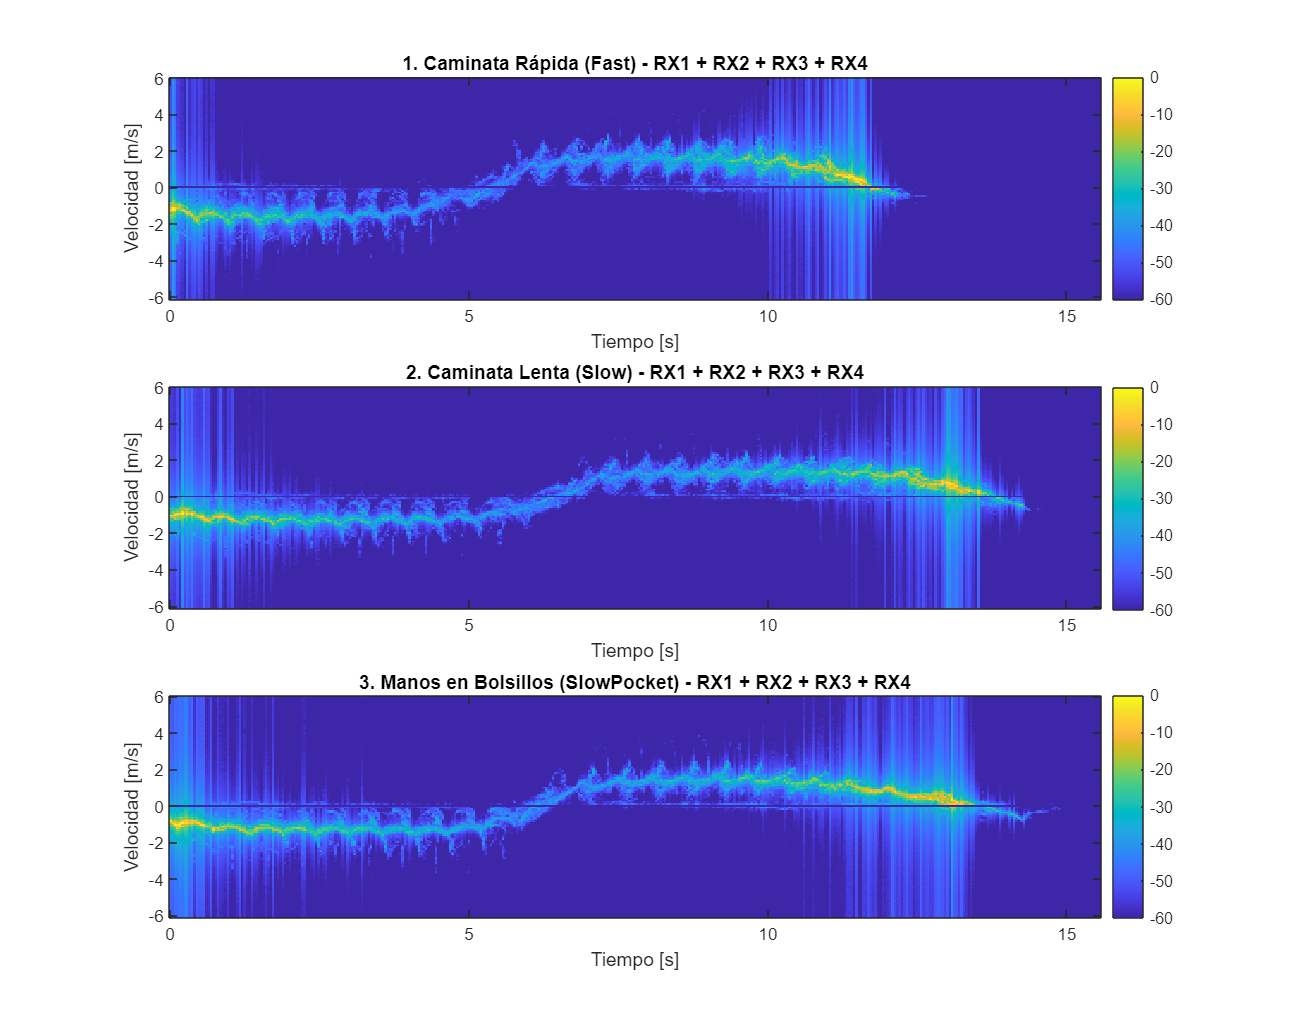

figure('Name', 'Comparativa Micro-Doppler Multicanal', 'Position', [100, 100, 950, 750]);

subplot(3, 1, 1);
imagesc(t_frames, v_axis, micro_dB_Fast);
axis xy;
colorbar;
clim([-60 0]);
title('1. Caminata Rápida (Fast) - RX1 + RX2 + RX3 + RX4');
xlabel('Tiempo [s]');
ylabel('Velocidad [m/s]');

subplot(3, 1, 2);
imagesc(t_frames, v_axis, micro_dB_Slow);
axis xy;
colorbar;
clim([-60 0]);
title('2. Caminata Lenta (Slow) - RX1 + RX2 + RX3 + RX4');
xlabel('Tiempo [s]');
ylabel('Velocidad [m/s]');

subplot(3, 1, 3);
imagesc(t_frames, v_axis, micro_dB_SlowPocket);
axis xy;
colorbar;
clim([-60 0]);
title('3. Manos en Bolsillos (SlowPocket) - RX1 + RX2 + RX3 + RX4');
xlabel('Tiempo [s]');
ylabel('Velocidad [m/s]');